# Lab A Report

## Task 4.1 - Linearized EOM in State Space (SS) form

Equations of Motion:

    
$$m_b l_b \ddot{x}_w + (I_b + m_b l_b^2)\ddot{\theta}_b = m_b l_b g \theta_b + \left( \frac{2 K_e K_t}{R_m} + b_f \right)\left( \frac{\dot{x}_w}{l_w} + \dot{\theta}_b \right)  - \frac{2 K_t}{R_m}v_m$$


    
$$(\frac{I_w}{l_w} + l_w m_b + l_w m_w)\ddot{x}_w + m_b l_b l_w \ddot{\theta}_b =  - \left( \frac{2 K_e K_t}{R_m} + b_f \right)\left( \frac{\dot{x}_w}{l_w} + \dot{\theta}_b \right) + \frac{2 K_t}{R_m}v_m$$


In the form:


$$\dot{x} = Ax + Bu$$



$$y = Cx + Du$$


syms g b_f m_b l_b I_b m_w l_w I_w R_m L_m b_m K_e K_t
syms x_w theta_b v_m 

A = sym('A_%d%d', [4 4]);
B = sym('B_%d%d', [4 1]);
C = sym('C_%d%d', [1 4]);
D = sym('D_%d%d', [1 1]);

Alpha = sym('alpha_%d%d', [4 4]);
Beta = sym('beta_%d%d', [4 1]);
Gamma = sym('gamma_%d%d', [4 4]);

Alpha(:,:) = 0;
Alpha(1,2) = 1;
Alpha(2,2) = ((2*K_e*K_t)/(R_m*l_w)) + (b_f/l_w);
Alpha(2,3) = m_b*l_b*g;
Alpha(2,4) = -((2*K_e*K_t)/R_m) - b_f;
Alpha(3,4) = 1;
Alpha(4,2) = -((2*K_e*K_t)/(R_m*l_w)) - (b_f/l_w);
Alpha(4,4) = ((2*K_e*K_t)/R_m) + b_f;
Alpha

$$Alpha = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & \frac{b_{f}}{l_{w}}+\frac{2\,K_{e}\,K_{t}}{R_{m}\,l_{w}} & g\,l_{b}\,m_{b} & -b_{f}-\frac{2\,K_{e}\,K_{t}}{R_{m}}\\ 0 & 0 & 0 & 1\\ 0 & -\frac{b_{f}}{l_{w}}-\frac{2\,K_{e}\,K_{t}}{R_{m}\,l_{w}} & 0 & b_{f}+\frac{2\,K_{e}\,K_{t}}{R_{m}} \end{array}\right)$$




Beta(:,:) = 0;
Beta(2,1) = -2*K_t/R_m;
Beta(4,1) = 2*K_t/R_m;
Beta

$$Beta = \left(\begin{array}{c} 0\\ -\frac{2\,K_{t}}{R_{m}}\\ 0\\ \frac{2\,K_{t}}{R_{m}} \end{array}\right)$$


Gamma(:,:) = 0;
Gamma(1,1) = 1;
Gamma(2,2) = m_b*l_b;
Gamma(2,4) = I_b + m_b*l_b^2;
Gamma(3,3) = 1;
Gamma(4,2) = (I_w/l_w) + l_w*m_b + l_w*m_w;
Gamma(4,4) = m_b * l_b * l_w;
Gamma

$$Gamma = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & l_{b}\,m_{b} & 0 & m_{b}\,{l_{b}}^{2}+I_{b}\\ 0 & 0 & 1 & 0\\ 0 & l_{w}\,m_{b}+l_{w}\,m_{w}+\frac{I_{w}}{l_{w}} & 0 & l_{b}\,l_{w}\,m_{b} \end{array}\right)$$



A = inv(Gamma)*Alpha

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{l_{w}\,\sigma_{5}\,\sigma_{2}}{\sigma_{1}}-\frac{l_{b}\,{l_{w}}^{2}\,m_{b}\,\sigma_{2}}{\sigma_{1}} & -\frac{g\,{l_{b}}^{2}\,{l_{w}}^{2}\,{m_{b}}^{2}}{\sigma_{1}} & \frac{l_{w}\,\sigma_{5}\,\sigma_{4}}{\sigma_{1}}+\frac{l_{b}\,{l_{w}}^{2}\,m_{b}\,\sigma_{4}}{\sigma_{1}}\\ 0 & 0 & 0 & 1\\ 0 & \frac{\sigma_{2}\,\sigma_{3}}{\sigma_{1}}+\frac{l_{b}\,l_{w}\,m_{b}\,\sigma_{2}}{\sigma_{1}} & \frac{g\,l_{b}\,m_{b}\,\sigma_{3}}{\sigma_{1}} & -\frac{\sigma_{4}\,\sigma_{3}}{\sigma_{1}}-\frac{l_{b}\,l_{w}\,m_{b}\,\sigma_{4}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{b}\,I_{w}+I_{b}\,{l_{w}}^{2}\,m_{b}+I_{w}\,{l_{b}}^{2}\,m_{b}+I_{b}\,{l_{w}}^{2}\,m_{w}+{l_{b}}^{2}\,{l_{w}}^{2}\,m_{b}\,m_{w}\\ \sigma_{2}=\frac{b_{f}}{l_{w}}+\frac{2\,K_{e}\,K_{t}}{R_{m}\,l_{w}}\\ \sigma_{3}=I_{w}+{l_{w}}^{2}\,m_{b}+{l_{w}}^{2}\,m_{w}\\ \sigma_{4}=b_{f}+\frac{2\,K_{e}\,K_{t}}{R_{m}}\\ \sigma_{5}=m_{b}\,{l_{b}}^{2}+I_{b} \end{array}$$

B = inv(Gamma)*Beta

$$B = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{2\,K_{t}\,l_{w}\,\left(m_{b}\,{l_{b}}^{2}+I_{b}\right)}{\sigma_{1}}+\frac{2\,K_{t}\,l_{b}\,{l_{w}}^{2}\,m_{b}}{\sigma_{1}}\\ 0\\ -\frac{2\,K_{t}\,\left(I_{w}+{l_{w}}^{2}\,m_{b}+{l_{w}}^{2}\,m_{w}\right)}{\sigma_{1}}-\frac{2\,K_{t}\,l_{b}\,l_{w}\,m_{b}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{m}\,\left(I_{b}\,I_{w}+I_{b}\,{l_{w}}^{2}\,m_{b}+I_{w}\,{l_{b}}^{2}\,m_{b}+I_{b}\,{l_{w}}^{2}\,m_{w}+{l_{b}}^{2}\,{l_{w}}^{2}\,m_{b}\,m_{w}\right) \end{array}$$

C = [0, 0, 1, 0]

C =      0     0     1     0


D = [0]

D =      0


### Subtitute Parameter Numerical Values


PARAMS = [g, b_f, m_b, l_b, I_b, m_w, l_w, I_w, R_m, L_m, b_m, K_e, K_t];
VALUES = [9.8, 0, 0.463, 0.113, 0.00767, 0.026, 0.021, 0.00000573, 4.4, 0, 0, 0.444, 0.47]; 

A_val = round(subs(A,PARAMS,VALUES),1)

$$A\_val = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -773.8000 & -6.6000 & 16.2000\\ 0 & 0 & 0 & 1\\ 0 & 3.3132e+03 & 63.1000 & -69.6000 \end{array}\right)$$

B_val = round(subs(B,PARAMS,VALUES),4)

$$B\_val = \left(\begin{array}{c} 0\\ 36.5980\\ 0\\ -156.7072 \end{array}\right)$$

## Task 4.2 - Transfer Function of the LTI SS System

% to calculate with full acuracy
A_value = subs(A,PARAMS,VALUES);
B_value = subs(B,PARAMS,VALUES);
% Matrixes has to be first cast to doulbe to make command work correctly.
% Matlab handles the values infinit if they are not casted or other way
% handled
sys = ss(double(A_value),double(B_value  ),C,D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0  -773.8  -6.574   16.25
   x3       0       0       0       1
   x4       0    3313   63.07  -69.58
 
  B = 
           u1
   x1       0
   x2    36.6
   x3       0
   x4  -156.7
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% to plot zero/pole/gain model use
G = zpk(sys)

G =
 
      -156.71 (s+0.007976)
  -----------------------------
  (s+843.4) (s+5.643) (s-5.679)
 
Continuous-time zero/pole/gain model.



% To plot pole-zero map
%pzplot(sys)
% To set only poles
poles = pole(sys)

poles =        -843.4
      -5.6426
       5.6787
            0


% To get the transfer function
tf(sys)

ans =
 
            -156.7 s - 1.25
  ------------------------------------
  s^3 + 843.4 s^2 - 62.47 s - 2.702e04
 
Continuous-time transfer function.



isstable(sys)

ans = logical
   0


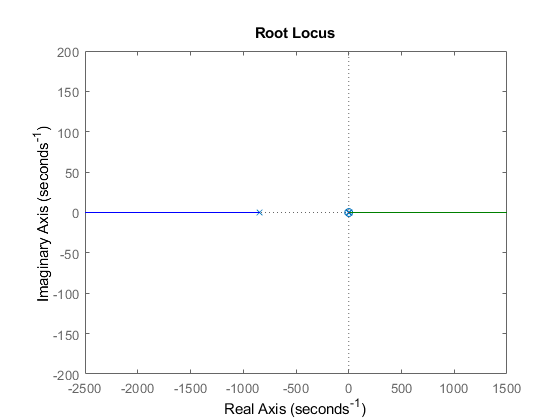

rlocus(sys)

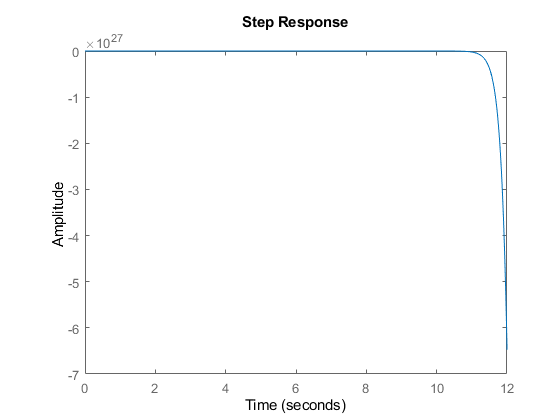

step(sys)

## Task 4.3 - PID Controller:

A = double(A_value)

A =             0            1            0            0
            0      -773.79      -6.5735        16.25
            0            0            0            1
            0       3313.2       63.072      -69.578


B= double(B_value)

B =             0
       36.598
            0
      -156.71


E= eig(double(A_value))

E =             0
       -843.4
      -5.6426
       5.6787


Desired Poles:

P= [0,-843.4002,-5.6422,-0.00001]

P =             0       -843.4      -5.6422       -1e-05


K= place(A, B, P)

K =   -3.4887e-19      -21.113      -30.726      -4.9671


Scaling Factor:

Acl= A-B*K

Acl =             0            1            0            0
   1.2768e-17      -1.0918       1117.9       198.03
            0            0            0            1
  -5.4671e-17       4.6406      -4751.9      -847.95


Ecl= eig(Acl)

Ecl =        -843.4
      -5.6422
  -9.4684e-15
  -9.9999e-06


Step Response:

syscl= ss(Acl, B, C, D)

syscl =
 
  A = 
               x1          x2          x3          x4
   x1           0           1           0           0
   x2   1.277e-17      -1.092        1118         198
   x3           0           0           0           1
   x4  -5.467e-17       4.641       -4752        -848
 
  B = 
           u1
   x1       0
   x2    36.6
   x3       0
   x4  -156.7
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



isstable(syscl)

ans = logical
   1


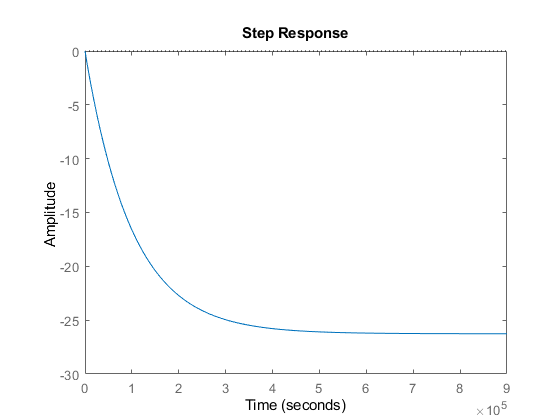

step(syscl)

zpk(syscl)

ans =
 
      -156.71 s (s+0.007976)
  -------------------------------
  s (s+843.4) (s+5.642) (s+1e-05)
 
Continuous-time zero/pole/gain model.



tf(syscl)

ans =
 
                -156.7 s^2 - 1.25 s
  ------------------------------------------------
  s^4 + 849 s^3 + 4759 s^2 + 0.04759 s + 4.489e-16
 
Continuous-time transfer function.



Kdc= dcgain(syscl)

Kdc =   -6.7763e-16


Kr= 1/Kdc

Kr =   -1.4757e+15


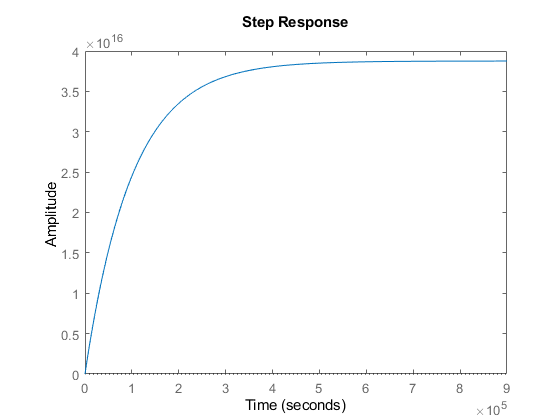

syscl_scaled= ss(Acl, B*Kr, C, D);
step(syscl_scaled)

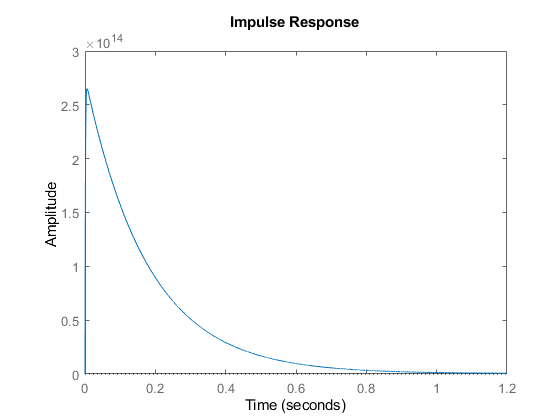

impulse(syscl_scaled)

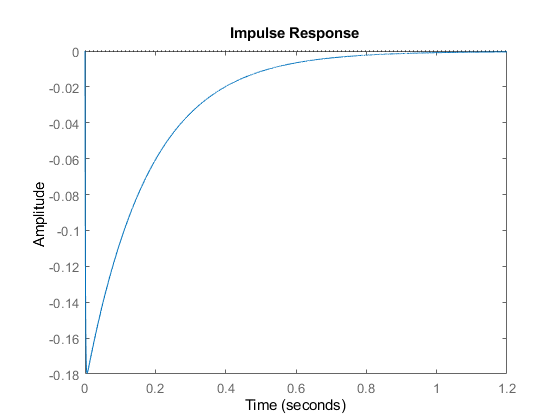

impulse(syscl)

## Task 4.3 - Design PID controller 

P(s)= (K_p + K_i / s +k_d * s) 

H(s)=(P(s)*K(s))/(1+P(s)*K(s))

%p1=-843.4002
%p2=-5.6422
%then we select p3 to negative real side so this time to -5
%p3=-5
%K=-156.71

syms s Kp Ki Kd p1 p2 p3 K
Ps=K*s/((s-p1)*(s-p2)*(s-p3))

$$Ps = -\frac{K\,s}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}$$


Ks=(Kp+Ki/s+Kd*s)

$$Ks = \mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}$$


$$\textrm{Ks}=\textrm{Kp}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}$$




% The closed loop system with PID and proces

Hs=(Ps*Ks)/(1+Ps*Ks)

$$Hs = \frac{K\,s\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)\,\left(\frac{K\,s\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}-1\right)}$$


$$\frac{K\,s\,{\left(\textrm{Ki}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}\right)}}{{\left(p_1 -s\right)}\,{\left(p_2 -s\right)}\,{\left(p_3 -s\right)}\,{\left(\frac{K\,s\,{\left(\textrm{Ki}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}\right)}}{{\left(p_1 -s\right)}\,{\left(p_2 -s\right)}\,{\left(p_3 -s\right)}}-1\right)}}$$


p1=-843.4002

p1 =        -843.4


p2=-5.6422

p2 =       -5.6422


%then we select p3 to negative real side so this time to -5
p3=-5

p3 =     -5


% K=-156.71
% Ps=K*s/((s-p1)*(s-p2)*(s-p3))
% Ks=(Kp+Ki/s+Kd*s)
% Hs=(Ps*Ks)/(1+Ps*Ks)


$$\frac{15671\,s\,{\left(\textrm{Kp}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}\right)}}{100\,{\left(s+\frac{231832081692151}{274877906944}\right)}\,{\left(\frac{15671\,s\,{\left(\textrm{Kp}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}\right)}}{100\,{\left(s+\frac{231832081692151}{274877906944}\right)}\,{\left(s+5\right)}\,{\left(s+\frac{28211}{5000}\right)}}-1\right)}\,{\left(s+5\right)}\,{\left(s+\frac{28211}{5000}\right)}}$$


Earlier values from PID tuner were

kp -355.5263

ki 1.0256e+04

kd -1.2450

But al poles did not go to the correct

Another PID tuner values 

kp -558.3481

ki -13776.6318

kd -0.87072

## Task 4.3 - Design PID controller 


$$G_{PID}(s)= K_p + \frac{K_i} {s} +\frac{K_ds}{1+\frac{K_ds}{N}}$$
 

H(s)=(P(s)*K(s))/(1+P(s)*K(s))

syms s K_p K_i K_d p_1 p_2 p_3 K N
P_s=K*s/((s-p_1)*(s-p_2)*(s-p_3))

$$P\_s = -\frac{K\,s}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}$$

K_s=K_p+K_i/s+(K_d*s/(1+(K_d*s/N)))

$$K\_s = K_{p}+\frac{K_{i}}{s}+\frac{K_{d}\,s}{\frac{K_{d}\,s}{N}+1}$$

H_s=(P_s*K_s)/(1+P_s*K_s)

$$H\_s = \frac{K\,s\,\left(K_{p}+\frac{K_{i}}{s}+\frac{K_{d}\,s}{\frac{K_{d}\,s}{N}+1}\right)}{\left(\frac{K\,s\,\left(K_{p}+\frac{K_{i}}{s}+\frac{K_{d}\,s}{\frac{K_{d}\,s}{N}+1}\right)}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}-1\right)\,\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}$$


poles

poles =        -843.4
      -5.6426
       5.6787
            0



p1=-843.4002

p1 =        -843.4


p2=-5.6422

p2 =       -5.6422


%then we select p3 to negative real side so this time to -5
p3=-5

p3 =     -5


K=-156.71

K =       -156.71


Ps=K*s/((s-p1)*(s-p2)*(s-p3))

$$Ps = -\frac{156.7100\,s}{\left(s+5.6422\right)\,\left(s+843.4002\right)\,\left(s+5\right)}$$

Ks=(Kp+Ki/s+Kd*s)

$$Ks = \mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}$$

Hs=(Ps*Ks)/(1+Ps*Ks)

$$Hs = \frac{156.7100\,s\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{\left(\frac{156.7100\,s\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{\left(s+5.6422\right)\,\left(s+843.4002\right)\,\left(s+5\right)}-1\right)\,\left(s+5.6422\right)\,\left(s+843.4002\right)\,\left(s+5\right)}$$

## **Task 5.2 - Controlability and obsevability**

format shortg
C = ctrb(A_value,B_value)

C =             0       36.598       -30865   2.6031e+07
       36.598       -30865   2.6031e+07  -2.1955e+10
            0      -156.71   1.3216e+05  -1.1147e+08
      -156.71   1.3216e+05  -1.1147e+08   9.4011e+10


 CLatex= latex(sym(C))

CLatex = '\left(\begin{array}{cccc} 0 & 36.5980 & -30865 & 26031000\\ 36.5980 & -30865 & 26031000 & -2.1955e+10\\ 0 & -156.7072 & 132160 & -111470000\\ -156.7072 & 132160 & -111470000 & 9.4011e+10 \end{array}\right)'

Observabilityh

O=obsv(A_value,C)

O =             0       36.598       -30865   2.6031e+07
       36.598       -30865   2.6031e+07  -2.1955e+10
            0      -156.71   1.3216e+05  -1.1147e+08
      -156.71   1.3216e+05  -1.1147e+08   9.4011e+10
            0   8.6247e+10   1.6418e+09  -1.8112e+09
            0  -7.2742e+13  -1.3847e+12   1.5276e+12
            0  -3.6933e+11  -7.0306e+09    7.756e+09
            0   3.1148e+14   5.9295e+12  -6.5412e+12
            0  -7.2738e+13  -6.8118e+11   1.5291e+12
            0   6.1348e+16   5.7452e+14  -1.2897e+15


 OLatex= latex(sym(O))

OLatex = '\left(\begin{array}{cccc} 0 & 36.5980 & -30865 & 26031000\\ 36.5980 & -30865 & 26031000 & -2.1955e+10\\ 0 & -156.7072 & 132160 & -111470000\\ -156.7072 & 132160 & -111470000 & 9.4011e+10\\ 0 & 8.6247e+10 & 1.6418e+09 & -1.8112e+09\\ 0 & -7.2742e+13 & -1.3847e+12 & 1.5276e+12\\ 0 & -3.6933e+11 & -7.0306e+09 & 7.7560e+09\\ 0 & 3.1148e+14 & 5.9295e+12 & -6.5412e+12\\ 0 & -7.2738e+13 & -6.8118e+11 & 1.5291e+12\\ 0 & 6.1348e+16 & 5.7452e+14 & -1.2897e+15\\ 0 & 3.1148e+14 & 2.9170e+12 & -6.5481e+12\\ 0 & -2.6269e+17 & -2.4601e+15 & 5.5224e+15\\ 0 & 6.1350e+16 & 5.7459e+14 & -1.2890e+15\\ 0 & -5.1743e+19 & -4.8462e+17 & 1.0872e+18\\ 0 & -2.6271e+17 & -2.4605e+15 & 5.5199e+15\\ 0 & 2.2156e+20 & 2.0751e+18 & -4.6553e+18 \end{array}\right)'

rank(C,1e-16)

ans =      4


rank(O,1e-16)

ans =      4
